run("D:\桌面\UVMS\Matlab\AUV_Shark H_infity Roubust Control\code\system_parameter.mlx")

m = 16.5000

W = 162

b = 162

L = 0.7615

d = 0.0220

Ix = 0.1280

Iy = 0.9410

Iz = 0.9716

Ixy = 0

Ixz = 0

Iyz = 0

xG = 0

yG = 0

zG = 0

xB = 0

yB = 0

zB = -0.0100

BGz = 0.0100

Yvt = 0.1670

Yht = 0.1670

Xudot = -6.4800

Xvdot = 0

Xwdot = 0

Yvdot = -19.2700

Ywdot = 0

Zudot = 0

Zwdot = -26.3900

Xpdot = 0

Xqdot = 0

Xrdot = 0

Ypdot = 0

Yqdot = 0

Yrdot = -0.1200

Zpdot = 0

Zqdot = -2.2000

Zrdot = 0

Kvdot = 0

Mudot = 0

Mwdot = -0.9400

Nvdot = 0.7200

Kpdot = -2.2000

Kqdot = 0

Krdot = 0

Mqdot = 0.5600

Mrdot = 0

Npdot = 0

Nrdot = -0.4800

Xu = -20.4000

Yv = -13.5100

Zw = -42.8800

Yp = 0

Yr = -9.3900

Zq = -17.0800

Kv = 0

Mw = -12.4100

Nv = 4.3100

Kp = -17.0800

Kr = 0

Mq = -6.0300

Np = 0

Nr = -1.5500

Xuu = -18.2000

Yuv = 0

Yvv = -34.2500

Zuw = 0

Zww = -87.3300

Yur = 0

Yvr = 0

Yrv = 111.8700

Zuq = 0

Muw = 0

Nuv = 0

Nvv = 0

Muq = 0

Nur = 0

Nvr = 0

Nrv = 0

Yrr = 0

Kpp = -5

Mqq = -5

Nrr = -8.2400

m11 = 22.9800

m22 = 35.7700

m33 = 42.8900

m44 = 2.3280

m55 = 0.3810

m66 = 1.4516

Du = 0

Dv = 0

Dw = 0

Dp = 0

Dq = 0

Dr = 0

syms signu signv signw signp signq signr Tp Ts Tpv Tsv u v w p q r x y z phi theta psi

% linearize by parameter matrix
nu = [u v w p q r].'

$$nu = \left(\begin{array}{c} u\\ v\\ w\\ p\\ q\\ r \end{array}\right)$$

eta = [x y z phi theta psi].'

$$eta = \left(\begin{array}{c} x\\ y\\ z\\ \varphi \\ \theta \\ \psi \end{array}\right)$$

x = [u v w p q r x y z phi theta psi].'

$$x = \left(\begin{array}{c} u\\ v\\ w\\ p\\ q\\ r\\ x\\ y\\ z\\ \varphi \\ \theta \\ \psi \end{array}\right)$$

U = [Tp Ts Tpv Tsv].'

$$U = \left(\begin{array}{c} \mathrm{Tp}\\ \mathrm{Ts}\\ \mathrm{Tpv}\\ \mathrm{Tsv} \end{array}\right)$$

a1 = Xudot*u + Xvdot*v + Xwdot*w + Xpdot*p + Xqdot*q + Xrdot*r

$$a1 = -\frac{162\,u}{25}$$

a2 = Xvdot*u + Yvdot*v + Ywdot*w + Ypdot*p + Yqdot*q + Yrdot*r

$$a2 = -\frac{3\,r}{25}-\frac{1927\,v}{100}$$

a3 = Xwdot*u + Ywdot*v + Zwdot*w + Zpdot*p + Zqdot*q + Zrdot*r

$$a3 = -\frac{11\,q}{5}-\frac{2639\,w}{100}$$

b1 = Xpdot*u + Ypdot*v + Zpdot*w + Kpdot*p + Kqdot*q + Krdot*r

$$b1 = -\frac{11\,p}{5}$$

b2 = Xqdot*u + Yqdot*v + Zqdot*w + Kqdot*p + Mqdot*q + Mrdot*r

$$b2 = \frac{14\,q}{25}-\frac{11\,w}{5}$$

b3 = Xrdot*u + Yrdot*v + Zrdot*w + Krdot*p + Mrdot*q + Nrdot*r

$$b3 = -\frac{12\,r}{25}-\frac{3\,v}{25}$$


% M
m11 = m - Xudot

m11 = 22.9800

m22 = m - Yvdot

m22 = 35.7700

m33 = m - Zwdot

m33 = 42.8900

m44 = Ix - Kpdot

m44 = 2.3280

m55 = Iy - Mqdot

m55 = 0.3810

m66 = Iz - Nrdot

m66 = 1.4516


M = [m11            0           -Xwdot          0              -Xqdot           0;
     0              m22         0               -Ypdot         0                -Yrdot;
     -Zudot         0           m33             0              -Zqdot           0;
     0              -Kvdot      0               m44            0                -Krdot;
     -Mudot         0           -Mwdot          0              m55              0;
     0              -Nvdot      0               -Npdot         0                m66]

M =    22.9800         0         0         0         0         0
         0   35.7700         0         0         0    0.1200
         0         0   42.8900         0    2.2000         0
         0         0         0    2.3280         0         0
         0         0    0.9400         0    0.3810         0
         0   -0.7200         0         0         0    1.4516



% CRB(nu)
CRB = [0          0           0           0           m*w             -m*v;
       0          0           0           -m*w        0               m*u ;
       0          0           0           m*v         -m*u            0     ;
       0          m*w         -m*v        0           Iz*r            -Iy*q;
       -m*w       0           m*u         -Iz*r       0               Ix*p ;
       m*v        -m*u        0           Iy*q        -Ix*p           0     ]

$$CRB = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & \frac{33\,w}{2} & \sigma_{2}\\ 0 & 0 & 0 & \sigma_{1} & 0 & \frac{33\,u}{2}\\ 0 & 0 & 0 & \frac{33\,v}{2} & \sigma_{3} & 0\\ 0 & \frac{33\,w}{2} & \sigma_{2} & 0 & \frac{2429\,r}{2500} & -\frac{941\,q}{1000}\\ \sigma_{1} & 0 & \frac{33\,u}{2} & -\frac{2429\,r}{2500} & 0 & \frac{16\,p}{125}\\ \frac{33\,v}{2} & \sigma_{3} & 0 & \frac{941\,q}{1000} & -\frac{16\,p}{125} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{33\,w}{2}\\ \sigma_{2}=-\frac{33\,v}{2}\\ \sigma_{3}=-\frac{33\,u}{2} \end{array}$$


% CA(nu)
CA = [0         0       0       0      -a3      a2
      0         0       0       a3     0        -a1
      0         0       0       -a2    a1       0
      0         -a3     a2      0      -b3      b2
      a3        0       -a1     b3      0       -b1
      -a2       a1      0       -b2     b1      0]

$$CA = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & \sigma_{2} & \sigma_{3}\\ 0 & 0 & 0 & \sigma_{1} & 0 & \frac{162\,u}{25}\\ 0 & 0 & 0 & \sigma_{4} & \sigma_{5} & 0\\ 0 & \sigma_{2} & \sigma_{3} & 0 & \frac{12\,r}{25}+\frac{3\,v}{25} & \frac{14\,q}{25}-\frac{11\,w}{5}\\ \sigma_{1} & 0 & \frac{162\,u}{25} & -\frac{12\,r}{25}-\frac{3\,v}{25} & 0 & \frac{11\,p}{5}\\ \sigma_{4} & \sigma_{5} & 0 & \frac{11\,w}{5}-\frac{14\,q}{25} & -\frac{11\,p}{5} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{11\,q}{5}-\frac{2639\,w}{100}\\ \sigma_{2}=\frac{11\,q}{5}+\frac{2639\,w}{100}\\ \sigma_{3}=-\frac{3\,r}{25}-\frac{1927\,v}{100}\\ \sigma_{4}=\frac{3\,r}{25}+\frac{1927\,v}{100}\\ \sigma_{5}=-\frac{162\,u}{25} \end{array}$$


% C(nu)
Cnu = CRB + CA

$$Cnu = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & \sigma_{2} & \sigma_{3}\\ 0 & 0 & 0 & \sigma_{1} & 0 & \frac{1149\,u}{50}\\ 0 & 0 & 0 & \sigma_{4} & \sigma_{5} & 0\\ 0 & \sigma_{2} & \sigma_{3} & 0 & \frac{3629\,r}{2500}+\frac{3\,v}{25} & -\frac{381\,q}{1000}-\frac{11\,w}{5}\\ \sigma_{1} & 0 & \frac{1149\,u}{50} & -\frac{3629\,r}{2500}-\frac{3\,v}{25} & 0 & \frac{291\,p}{125}\\ \sigma_{4} & \sigma_{5} & 0 & \frac{381\,q}{1000}+\frac{11\,w}{5} & -\frac{291\,p}{125} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{11\,q}{5}-\frac{4289\,w}{100}\\ \sigma_{2}=\frac{11\,q}{5}+\frac{4289\,w}{100}\\ \sigma_{3}=-\frac{3\,r}{25}-\frac{3577\,v}{100}\\ \sigma_{4}=\frac{3\,r}{25}+\frac{3577\,v}{100}\\ \sigma_{5}=-\frac{1149\,u}{50} \end{array}$$


fc = Cnu*nu

$$fc = \begin{array}{l} \left(\begin{array}{c} q\,\sigma_{1}-r\,\sigma_{2}\\ \frac{1149\,r\,u}{50}-p\,\sigma_{1}\\ p\,\sigma_{2}-\frac{1149\,q\,u}{50}\\ q\,\sigma_{3}-r\,\sigma_{4}+v\,\sigma_{1}-w\,\sigma_{2}\\ \frac{291\,p\,r}{125}+\frac{1149\,u\,w}{50}-p\,\sigma_{3}-u\,\sigma_{1}\\ p\,\sigma_{4}-\frac{1149\,u\,v}{50}-\frac{291\,p\,q}{125}+u\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{11\,q}{5}+\frac{4289\,w}{100}\\ \sigma_{2}=\frac{3\,r}{25}+\frac{3577\,v}{100}\\ \sigma_{3}=\frac{3629\,r}{2500}+\frac{3\,v}{25}\\ \sigma_{4}=\frac{381\,q}{1000}+\frac{11\,w}{5} \end{array}$$



% C(t)
Ct = jacobian(fc,nu)

$$Ct = \left(\begin{array}{cccccc} 0 & -\frac{3577\,r}{100} & \frac{4289\,q}{100} & 0 & \frac{22\,q}{5}+\frac{4289\,w}{100} & -\frac{6\,r}{25}-\frac{3577\,v}{100}\\ \frac{1149\,r}{50} & 0 & -\frac{4289\,p}{100} & -\frac{11\,q}{5}-\frac{4289\,w}{100} & -\frac{11\,p}{5} & \frac{1149\,u}{50}\\ -\frac{1149\,q}{50} & \frac{3577\,p}{100} & 0 & \frac{3\,r}{25}+\frac{3577\,v}{100} & -\frac{1149\,u}{50} & \frac{3\,p}{25}\\ 0 & \frac{58\,q}{25}+\frac{178\,w}{25} & \frac{178\,v}{25}-\frac{58\,r}{25} & 0 & \frac{5353\,r}{5000}+\frac{58\,v}{25} & \frac{5353\,q}{5000}-\frac{58\,w}{25}\\ -\frac{11\,q}{5}-\frac{1991\,w}{100} & -\frac{3\,p}{25} & -\frac{1991\,u}{100} & \frac{2191\,r}{2500}-\frac{3\,v}{25} & -\frac{11\,u}{5} & \frac{2191\,p}{2500}\\ \frac{3\,r}{25}+\frac{1279\,v}{100} & \frac{1279\,u}{100} & \frac{11\,p}{5} & \frac{11\,w}{5}-\frac{1947\,q}{1000} & -\frac{1947\,p}{1000} & \frac{3\,u}{25} \end{array}\right)$$


% D(nu)
Dnu = -[Xu+Xuu*u*signu        0                                    0                   0                   0                   0;
        0                    Yv+Yvv*v*signv+Yrv*r*signr            0                   Yp                  0                   Yr+Yvr*v*signv+Yrr*r*signr;
        0                    0                                    Zw+Zww*w*signw       0                   Zq                  0;
        0                    Kv                                   0                   Kp+Kpp*p*signp       0                   Kr;
        0                    0                                    Mw                  0                   Mq+Mqq*q*signq       0;
        0                    Nv+Nvv*v*signv+Nrv*r*signr             0                   Np                  0                   Nr+Nrr*r*signr+Nvr*v*signv]

$$Dnu = \left(\begin{array}{cccccc} \frac{91\,\mathrm{signu}\,u}{5}+\frac{102}{5} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{137\,\mathrm{signv}\,v}{4}-\frac{11187\,r\,\mathrm{signr}}{100}+\frac{1351}{100} & 0 & 0 & 0 & \frac{939}{100}\\ 0 & 0 & \frac{8733\,\mathrm{signw}\,w}{100}+\frac{1072}{25} & 0 & \frac{427}{25} & 0\\ 0 & 0 & 0 & 5\,p\,\mathrm{signp}+\frac{427}{25} & 0 & 0\\ 0 & 0 & \frac{1241}{100} & 0 & 5\,q\,\mathrm{signq}+\frac{603}{100} & 0\\ 0 & -\frac{431}{100} & 0 & 0 & 0 & \frac{206\,r\,\mathrm{signr}}{25}+\frac{31}{20} \end{array}\right)$$


fd = Dnu*nu

$$fd = \left(\begin{array}{c} u\,\left(\frac{91\,\mathrm{signu}\,u}{5}+\frac{102}{5}\right)\\ \frac{939\,r}{100}+v\,\left(\frac{137\,\mathrm{signv}\,v}{4}-\frac{11187\,r\,\mathrm{signr}}{100}+\frac{1351}{100}\right)\\ \frac{427\,q}{25}+w\,\left(\frac{8733\,\mathrm{signw}\,w}{100}+\frac{1072}{25}\right)\\ p\,\left(5\,p\,\mathrm{signp}+\frac{427}{25}\right)\\ \frac{1241\,w}{100}+q\,\left(5\,q\,\mathrm{signq}+\frac{603}{100}\right)\\ r\,\left(\frac{206\,r\,\mathrm{signr}}{25}+\frac{31}{20}\right)-\frac{431\,v}{100} \end{array}\right)$$


% D(t)
Dt = jacobian(fd,nu)

$$Dt = \left(\begin{array}{cccccc} \frac{182\,\mathrm{signu}\,u}{5}+\frac{102}{5} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{137\,\mathrm{signv}\,v}{2}-\frac{11187\,r\,\mathrm{signr}}{100}+\frac{1351}{100} & 0 & 0 & 0 & \frac{939}{100}-\frac{11187\,\mathrm{signr}\,v}{100}\\ 0 & 0 & \frac{8733\,\mathrm{signw}\,w}{50}+\frac{1072}{25} & 0 & \frac{427}{25} & 0\\ 0 & 0 & 0 & 10\,p\,\mathrm{signp}+\frac{427}{25} & 0 & 0\\ 0 & 0 & \frac{1241}{100} & 0 & 10\,q\,\mathrm{signq}+\frac{603}{100} & 0\\ 0 & -\frac{431}{100} & 0 & 0 & 0 & \frac{412\,r\,\mathrm{signr}}{25}+\frac{31}{20} \end{array}\right)$$


% G(t)
Gt = [0      0       0       0                               (W-b)*cos(theta)                0
     0      0       0       -(W-b)*cos(theta)*cos(phi)      (W-b)*sin(theta)*sin(phi)       0
     0      0       0       (W-b)*cos(theta)*sin(phi)       (W-b)*sin(theta)*cos(phi)       0
     0      0       0       -zB*b*cos(theta)*cos(phi)       zB*b*sin(theta)*sin(phi)        0
     0      0       0       0                               -zB*b*cos(theta)                0
     0      0       0       0                               0                               0]

$$Gt = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{81\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{50} & -\frac{81\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{50} & 0\\ 0 & 0 & 0 & 0 & \frac{81\,\cos\left(\theta \right)}{50} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


% g(eta)
geta = [   (W-b)*sin(theta);
        -(W-b)*cos(theta)*sin(phi);
        -(W-b)*cos(theta)*cos(phi);
        -zB*b*cos(theta)*sin(phi);
        -zB*b*sin(theta);
                    0             ]

$$geta = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{81\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{50}\\ \frac{81\,\sin\left(\theta \right)}{50}\\ 0 \end{array}\right)$$


% J(eta)
J1 = [cos(psi)*cos(theta)     -sin(psi)*cos(phi)+cos(psi)*sin(theta)*sin(phi)    sin(psi)*sin(phi)+cos(psi)*cos(phi)*sin(theta)
      sin(psi)*cos(theta)     cos(psi)*cos(phi)+sin(phi)*sin(theta)*sin(psi)     -cos(psi)*sin(phi)+sin(theta)*sin(psi)*cos(phi)
      -sin(theta)             cos(theta)*sin(phi)                                cos(theta)*cos(phi)]

$$J1 = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


J2 = [1         sin(phi)*tan(theta)     cos(phi)*tan(theta)
      0         cos(phi)                -sin(phi)
      0         sin(phi)/cos(theta)     cos(phi)/cos(theta)]

$$J2 = \left(\begin{array}{ccc} 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$


J = blkdiag(J1, J2)

$$J = \left(\begin{array}{cccccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & 0 & 0 & 0\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & 0 & 0 & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & 0 & 0 & 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & 0 & 0 & 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$


fJ = J*nu

$$fJ = \left(\begin{array}{c} w\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)-v\,\left(\cos\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)+u\,\cos\left(\psi \right)\,\cos\left(\theta \right)\\ v\,\left(\cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)-w\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)+u\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ w\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-u\,\sin\left(\theta \right)+v\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ p+r\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+q\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ q\,\cos\left(\varphi \right)-r\,\sin\left(\varphi \right)\\ \frac{r\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{q\,\sin\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$


% Bu   u = tau = [X Y Z K M N]' = Bu*u', u' = [Tp   Ts   Tpv   Tsv]
Bu = [1     1       0       0;
      0     0       0       0;
      0     0       1       1;
      0     0       -Yvt    Yvt;
      0     0       0       0;
      Yht   -Yht    0       0]

Bu =     1.0000    1.0000         0         0
         0         0         0         0
         0         0    1.0000    1.0000
         0         0   -0.1670    0.1670
         0         0         0         0
    0.1670   -0.1670         0         0


tau = Bu*U

$$tau = \left(\begin{array}{c} \mathrm{Tp}+\mathrm{Ts}\\ 0\\ \mathrm{Tpv}+\mathrm{Tsv}\\ \frac{167\,\mathrm{Tsv}}{1000}-\frac{167\,\mathrm{Tpv}}{1000}\\ 0\\ \frac{167\,\mathrm{Tp}}{1000}-\frac{167\,\mathrm{Ts}}{1000} \end{array}\right)$$


% J(t)
f_nu = jacobian(fJ, nu)

$$f\_nu = \left(\begin{array}{cccccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & 0 & 0 & 0\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & 0 & 0 & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & 0 & 0 & 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & 0 & 0 & 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

f_eta = jacobian(fJ, eta)


% linearize by 12 EOM
% f = [-(Cnu+Dnu)*nu - geta + tau;J*nu]
% E = blkdiag(inv(M), eye(6))
% 
% A1 = E*jacobian(f, x)
% B1 = E*jacobian(f, U)

% longitudinal movement [u0 0 w0 0 0 0 0 0 0 0 psi0] 
syms signu signv signw signp signq signr u v w p q r x y z phi theta psi
u0 = 0.05

u0 = 0.0500

signu0 = 1

signu0 = 1

v0 = 0

v0 = 0

signv0 = signv  

$$signv0 = \mathrm{signv}$$

w0 = 0.04

w0 = 0.0400

signw0 = 1

signw0 = 1

p0 = 0

p0 = 0

signp0 = signp 

$$signp0 = \mathrm{signp}$$

q0 = 0

q0 = 0

signq0 = signq 

$$signq0 = \mathrm{signq}$$

r0 = 0

r0 = 0

signr0 = signr 

$$signr0 = \mathrm{signr}$$

% eta0
x0 = 0

x0 = 0

y0 = 0

y0 = 0

z0 = 0

z0 = 0

phi0 = 0

phi0 = 0

theta0 = 0

theta0 = 0

psi0 = 0

psi0 = 0


C = subs(Ct, [u, v, w, p, q, r], [u0, v0, w0, p0, q0, r0])

$$C = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & \frac{4289}{2500} & 0\\ 0 & 0 & 0 & -\frac{4289}{2500} & 0 & \frac{1149}{1000}\\ 0 & 0 & 0 & 0 & -\frac{1149}{1000} & 0\\ 0 & \frac{178}{625} & 0 & 0 & 0 & -\frac{58}{625}\\ -\frac{1991}{2500} & 0 & -\frac{1991}{2000} & 0 & -\frac{11}{100} & 0\\ 0 & \frac{1279}{2000} & 0 & \frac{11}{125} & 0 & \frac{3}{500} \end{array}\right)$$

D = subs(Dt,  [u, v, w, p, q, r, signu, signv, signw, signp, signq, signr], [u0, v0, w0, p0, q0, r0, signu0, signv0, signw0, signp0, signq0, signr0])

$$D = \left(\begin{array}{cccccc} \frac{1111}{50} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1351}{100} & 0 & 0 & 0 & \frac{939}{100}\\ 0 & 0 & \frac{62333}{1250} & 0 & \frac{427}{25} & 0\\ 0 & 0 & 0 & \frac{427}{25} & 0 & 0\\ 0 & 0 & \frac{1241}{100} & 0 & \frac{603}{100} & 0\\ 0 & -\frac{431}{100} & 0 & 0 & 0 & \frac{31}{20} \end{array}\right)$$

G = subs(Gt, [phi, theta, psi], [phi0, theta0, psi0])

$$G = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{81}{50} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{81}{50} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Jnu = subs(f_nu, [u, v, w, p, q, r, phi, theta, psi], [u0, v0, w0, p0, q0, r0, phi0, theta0, psi0])

$$Jnu = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

Jeta = subs(f_eta, [u, v, w, p, q, r, phi, theta, psi], [u0, v0, w0, p0, q0, r0, phi0, theta0, psi0])

$$Jeta = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & \frac{1}{25} & 0\\ 0 & 0 & 0 & -\frac{1}{25} & 0 & \frac{1}{20}\\ 0 & 0 & 0 & 0 & -\frac{1}{20} & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

% linearized state-space representation of full-order nonlinear model
Gss.A = double([-inv(M)*(C+D)  -inv(M)*G
                    Jnu           Jeta   ])

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0


Gss.B = [inv(M);zeros(6)]

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0


% A1 = subs(A1, [u, v, w, p, q, r, phi, theta, psi], [u0, v0, w0, p0, q0, r0, phi0, theta0, psi0])
% 
% B1 = subs(B1, [u, v, w, p, q, r, phi, theta, psi], [u0, v0, w0, p0, q0, r0, phi0, theta0, psi0])

Gss.C = eye(12)

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0


Gss.D = zeros(12,6)

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0


Gss = ss(Gss.A,Gss.B,Gss.C,Gss.D)

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0

Gss.InputName = {'X', 'Y', 'Z', 'K', 'M', 'N'}

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0

Gss.OutputName = {'u', 'v', 'w', 'p', 'q', 'r', 'x', 'y', 'z', 'phi', 'theta', 'psi'}

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1    -0.9669         0         0         0  -0.07466         0         0         0         0         0         0         0
   x2          0   -0.3855         0   0.04809         0   -0.2906         0         0         0         0         0         0
   x3    -0.1228         0    0.4283         0    0.4872         0         0         0         0         0    0.2497         0
   x4          0   -0.1223         0    -7.337         0   0.03986         0         0         0   -0.6959         0         0
   x5      2.393         0    -31.02         0    -16.74         0         0         0         0         0    -4.868         0
   x6          0     2.337         0  -0.03677         0    -1.216         0         0         0         0         0         0
   x7          1         0         0         0         0         0         0         0         0

% disp(Gss)
Gtf = tf(Gss)

Gtf =
 
  从输入 "X" 到输出...
       0.04352 s^3 + 0.7098 s^2 + 0.5575 s + 0.2463
   u:  ---------------------------------------------
       s^4 + 17.28 s^3 + 28.76 s^2 + 18.25 s + 5.473
 
   v:  0
 
           -0.005342 s^2 - 0.03868 s + 6.479e-18
   w:  ---------------------------------------------
       s^4 + 17.28 s^3 + 28.76 s^2 + 18.25 s + 5.473
 
   p:  0
 
             0.1041 s^2 + 0.1211 s + 1.365e-33
   q:  ---------------------------------------------
       s^4 + 17.28 s^3 + 28.76 s^2 + 18.25 s + 5.473
 
   r:  0
 
         0.04352 s^3 + 0.7098 s^2 + 0.5616 s + 0.2511
   x:  -------------------------------------------------
       s^5 + 17.28 s^4 + 28.76 s^3 + 18.25 s^2 + 5.473 s
 
   y:  0
 
             -0.005342 s^2 - 0.04389 s - 0.006054
   z:  -------------------------------------------------
       s^5 + 17.28 s^4 + 28.76 s^3 + 18.25 s^2 + 5.473 s
 
   phi:  0
 
                         0.1041 s + 0.1211
   theta:  ---------------------------------------------
          

% unforced response
x0 = [1, 0, 1, 0*pi/180, 0*pi/180, 0*pi/180, 0, 0, 0, 0*pi/180, 0*pi/180, 0*pi/180]

x0 =      1     0     1     0     0     0     0     0     0     0     0     0


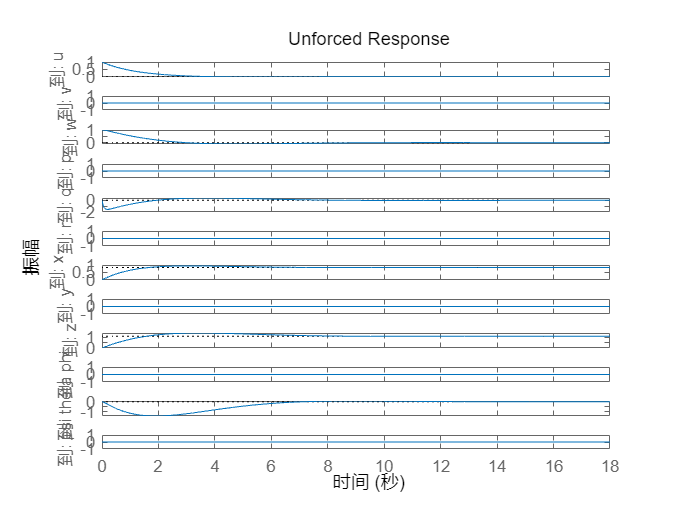

figure
initial(Gss, x0)
title('Unforced Response')

% step response
xplot_ylabel = ["u (m/s)" "v (m/s)" "w (m/s)" "p (deg/s)" "q (deg/s)" "r (deg/s)" "x (m)" "y (m)" "z (m)" "phi (deg)" "theta (deg)" "psi (deg)"]

xplot_ylabel = 1×12 string 数组
    "u (m/s)"    "v (m/s)"    "w (m/s)"    "p (deg/s)"    "q (deg/s)"    "r (deg/s)"    "x (m)"    "y (m)"    "z (m)"    "phi (deg)"    "theta (deg)"    "psi (deg)"


xplot_title = ["Surge" 'Sway' 'Heave' 'Roll Rate' 'Pitch Rate' 'Yaw Rate' 'Axial' 'Lat' 'Depth' 'Roll' 'Pitch' 'Yaw']

xplot_title = 1×12 string 数组
    "Surge"    "Sway"    "Heave"    "Roll Rate"    "Pitch Rate"    "Yaw Rate"    "Axial"    "Lat"    "Depth"    "Roll"    "Pitch"    "Yaw"


xbode = ["Surge" 'Sway' 'Heave' 'Roll' 'Pitch' 'Yaw']

xbode = 1×6 string 数组
    "Surge"    "Sway"    "Heave"    "Roll"    "Pitch"    "Yaw"


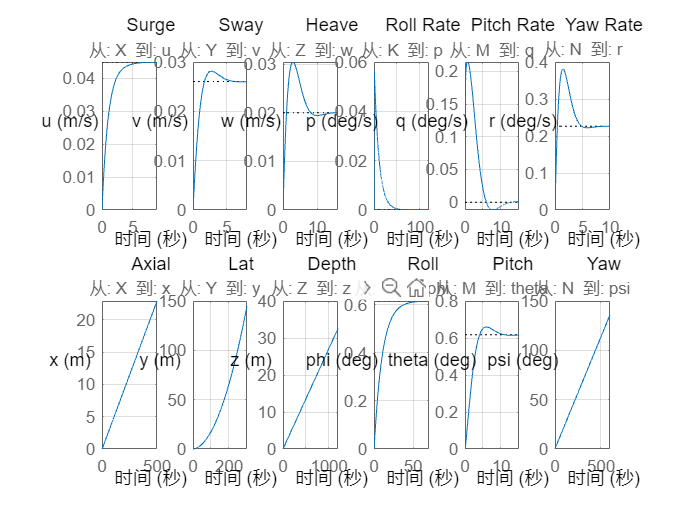

% subplot contrast 
figure('numbertitle','off','name','Linearized Model Step response'); 
hold on
for i = 1:6

    subplot(2,6,i)
    step(Gtf(i,i))% 2-order overdamped system
    ylabel(xplot_ylabel(i),'rotation',0)
    title(xplot_title(i))
    grid on

    subplot(2,6,i+6)
    step(Gtf(i+6,i))
    ylabel(xplot_ylabel(i+6),'rotation',0)
    title(xplot_title(i+6))
    grid on
end
hold off

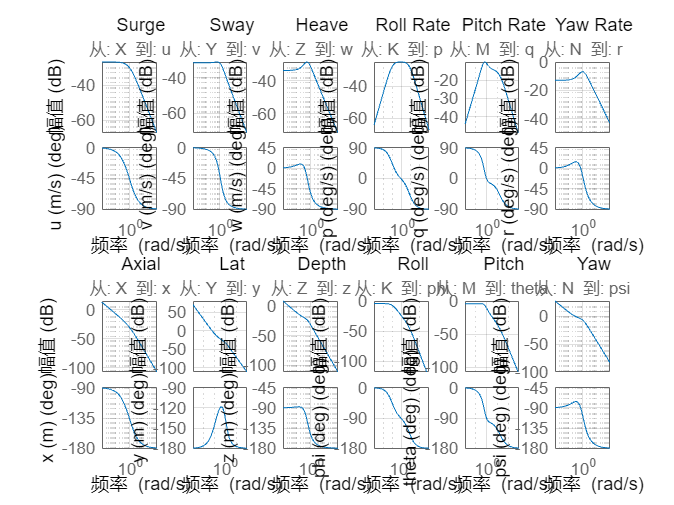


% figure;  
% hold on;
% for i = 1:6
%     subplot(2,6,i)
%     bode(Gtf(i,i))
%     ylabel(xplot_ylabel(i),'rotation',0)
%     title(xplot_title(i))
%     grid on
%     
%     subplot(2,6,i+6)
%     bode(Gtf(i+6,i)) 
%     ylabel(xplot_ylabel(i+6),'rotation',0)
%     title(xplot_title(i+6))
%     grid on
% end
% hold off